green=im2double(aligned_green);
norm_green = normalize(green(:), 'range', [0, 1]);
norm_green=reshape(norm_green,512,512);
imshow(norm_green);
blue=im2double(aligned_blue);
norm_blue = normalize(blue(:), 'range', [0, 1]);
norm_blue=reshape(norm_blue,512,512);
red=im2double(aligned_red);
norm_red = normalize(red(:), 'range', [0, 1]);
norm_red=reshape(norm_red,512,512);
calcium=im2double(calcium);
norm_calcium = normalize(calcium(:), 'range', [0, 1]);
norm_calcium=reshape(norm_calcium,512,512);

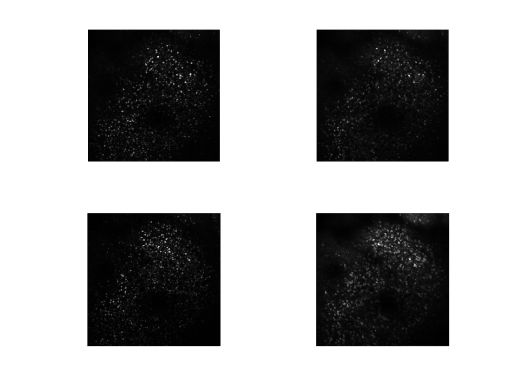

figure
subplot(2,2,1)
imshow(norm_red);
subplot(2,2,2)
imshow(norm_green);
subplot(2,2,3)
imshow(norm_blue);
subplot(2,2,4)
imshow(norm_calcium);

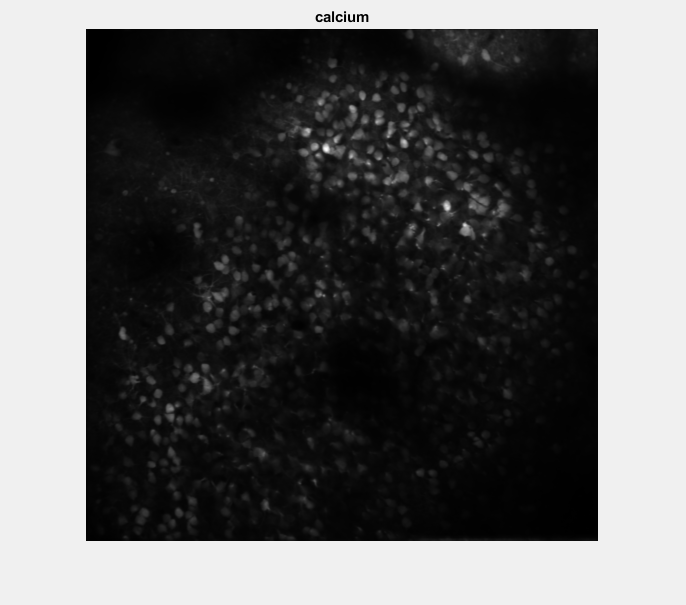

deconv_green=(norm_green-0.5*norm_calcium);
deconv_green(deconv_green<0)=0;
deconv_green=uint16(deconv_green*65536);
imwrite(deconv_green, ([path,'deconv_green.tif']), 'tif');
figure (Visible="on")

imshow(norm_calcium);title('calcium');

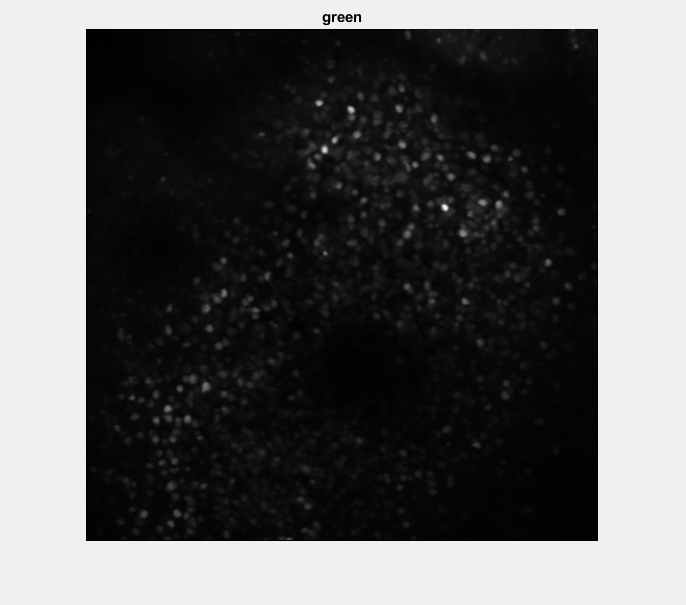

figure (Visible="on")
imshow(norm_green);title('green');

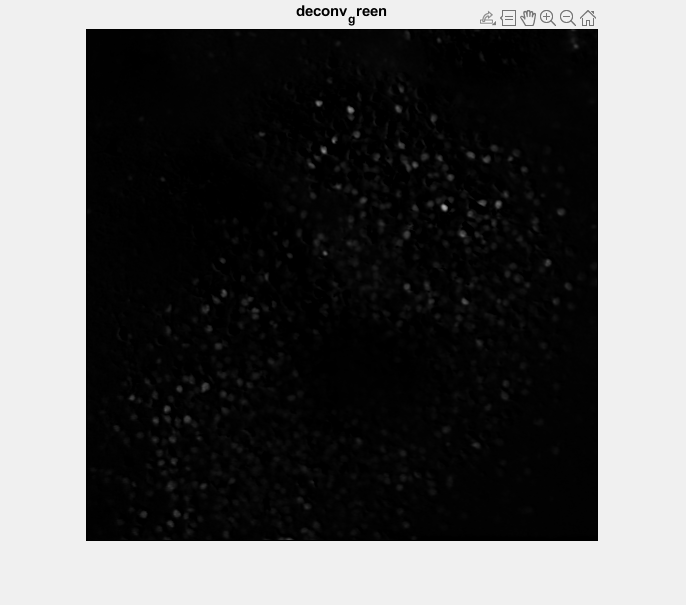

figure (Visible="on")
imshow(deconv_green);title('deconv_green');

composite(:,:,1)=norm_red*65536;
composite(:,:,2)=norm_green*65536;
composite(:,:,3)=norm_blue*65536;
figure
imshow(composite)